# POST-PROCESSING OF IMAGES FROM PLANAR KIRIGAMI EXPERIMENTS

"Continuum Field Theory for the Deformations of Planar Kirigami" Yue Zheng, Imtiar Niloy, Paolo Celli, Ian Tobasco, and Paul Plucinsky Phys. Rev. Lett. 128, 208003 ? Published 20 May 2022

% Code created on July 2021

close all;
clear all;
clc;

## INPUT NEEDED -- CHOICE OF SPECIMEN/EXPERIMENTAL RESULT TO ANALYZE

filename='061521_AnIsoLRSidesCenterPull_v2_7cm'; para = [3 100]; % for Hyperbolic Pulling

%filename='060821_IsoLRSidesCenterPull_6cm'; para = [0 42]; % for Elliptic Pulling
filename='060821_IsoLRSidesCenterPull_0cm'; para = [0 42]; % for Elliptic Pulling

% filename = '070121_ForcedIntoAnnulus_Hyperbolic'; para = [0 42]; % for Hyperbolic Annulus

% filename = '070121_ForcedIntoAnnulus_Elliptic'; para = [0 42]; % for Elliptic Annulus

%filename = '063021_Mixed_LRSidesCenterPull_6'; para = [0 100]; %Test for mixed

## IMAGE READ

I = imread([filename,'.tif']);

BW = imbinarize(I);
BW = logical(1 - BW);

stats = regionprops('table',BW,'Centroid','Area','MajorAxisLength','MinorAxisLength','Orientation');
Cent = stats.Centroid;
Area = stats.Area;
Maax = stats.MajorAxisLength;
Miax = stats.MinorAxisLength;
Orit = stats.Orientation;
Orit = -Orit/180*pi;

hinge = para(1);
Maax = Maax + hinge;
Maax(Maax>para(2))=para(2);

Angle=atan(Miax./Maax);
%xi_in = 0.32 %0.219; %For mixed kirigami
xi_in = 0.06; %0.06; %For hyperbolic kirigami
%xi_in = 0.09; %0.09; %For auxetic kirigami
Angle = Angle-xi_in;

## INPUT NEEDED -- CHOOSE SLIT THRESHOLDS

Slit=(Area>20 & Area<1000); % for Hyperbolic Pulling

%Slit=(Area>20 & Area<2300); % for Elliptic Pulling

% Slit=(Area>20 & Area<1000); % for Hyperbolic Annulus

% Slit=(Area>20 & Area<2000); % for Elliptic Annulus

%Slit=(Area>200 & Area<1700) & Maax < 60;% for Mixed Pulling

## PLOTS

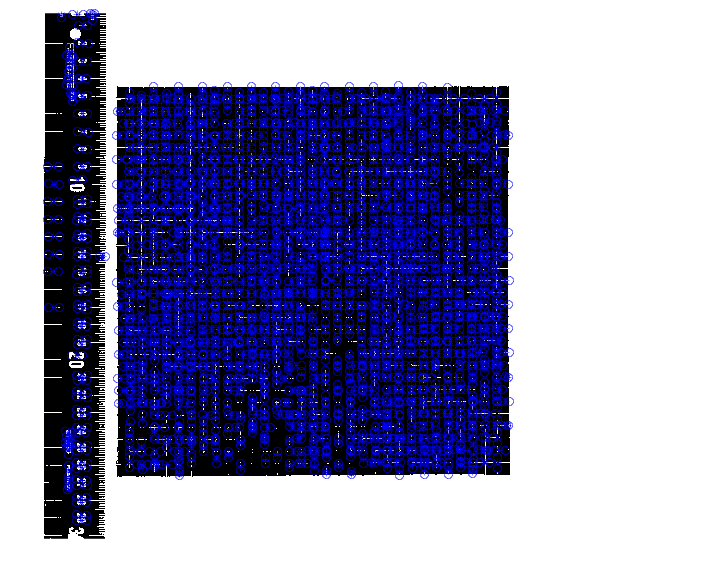

disp(Cent(Slit,1))
disp(Cent(Slit,2))
%disp(Angle(Slit))
%disp(Cent(Slit,1))

figure;
imshow(BW);
hold on;
plot(Cent(Slit,1),Cent(Slit,2),'b*')

plot([Cent(Slit,1)+Maax(Slit)/2.*cos(Orit(Slit)) Cent(Slit,1)-Maax(Slit)/2.*cos(Orit(Slit))]...
    ,[Cent(Slit,2)+Maax(Slit)/2.*sin(Orit(Slit)) Cent(Slit,2)-Maax(Slit)/2.*sin(Orit(Slit))],'bo')



figure;
subimage(BW);
hold on;
scatter2 = scatter(Cent(Slit,1),Cent(Slit,2),100,Angle(Slit),'filled')

scatter2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [42 40.3354 41.9018 39.7143 40.0429 43.4421 40.9409 43.1152 73.8239 101.1756 102.2705 101.0964 95.6111 102.2872 105.0570 103.2937 102.2629 106.6585 103.2554 99.6257 116.1146 102.6762 103.8904 99.7640 99.9740 99.7361 101.8824 … ]
              YData: [1.1456e+03 734.3665 871.6503 1.0084e+03 597.2454 665.9316 802.9785 939.8364 8.8521 1.6331e+03 1.6491e+03 1.6730e+03 1.6863e+03 1.7013e+03 183.2129 212.1561 239 258.7866 280.3377 1.7832e+03 191.9676 146.5619 164.5205 1.8130e+03 … ]
           SizeData: 100
              CData: [1711×1 double]

  Show 

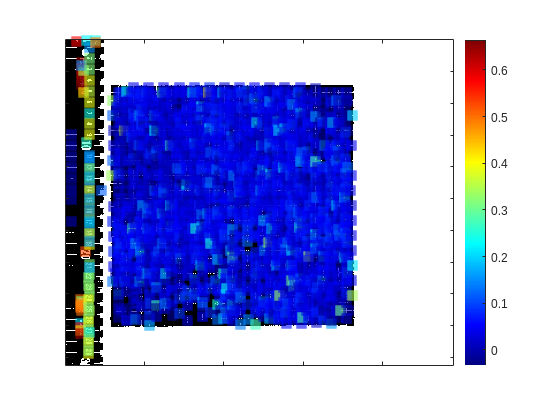

colormap jet;
scatter2.MarkerFaceAlpha = .6;
scatter2.Marker = 's';
set(gca,'XtickLabel',[],'YtickLabel',[])
colorbar